# Figure 10 - Consistency of our data with deVeld et al.

This paper has a published curve showing the mean autofluorescence spectra from the tongue and the cheek.  The original data set, which we sought but could not find, was measured in 96 subjects.  The means across the publication are plotted in the paper, and we scanned the data from the figure.

    *de Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, D. J., Star, W. M., & Roodenburg, J. L. (2003).  Autofluorescence characteristics of healthy oral mucosa at different anatomical sites. Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 32(5), 367-376*

The measurements were made over a small field of view using a fiber optic probe.  It had an 8 mm diameter.  We measured over ?? how large a field (2 deg) at some distance (500 mm ??).  That would be about 18 mm.  If it was 1 deg, then 9 mm, so a good match. The measured the cheeck.  We measured the lip.

The instrument claims a wavelength resolution of 1 nm, which we find very suspicious.

The measurements are in some ways consistent with our data

- The slope from 500nm-600nm is very similar in the two datasets

- We both see a 580 nm dip for the blood

- We both see the porphyrin peak around 640 nm

but do not match perfectly.  

- We see an uptick on the lip around 600nm which they do not report on their cheek

- We see a second peak on the tongue in some of our subjects at 670 nm which is not present on their mean

- We see a clear 540nm dip for blood on both lip and tongue; they do not.

ieInit;
waves = 500:5:700;
nWave = 520;
symbols = {'kx-','k*-','k^-','ko-'};
T = oeDatabaseCreate;

## Lip, all subjects at 405 nm

Read in the files at all excitation levels and all subjects.  The raw data have non integer wavelengths from the grabit.  That is why we round(wave).

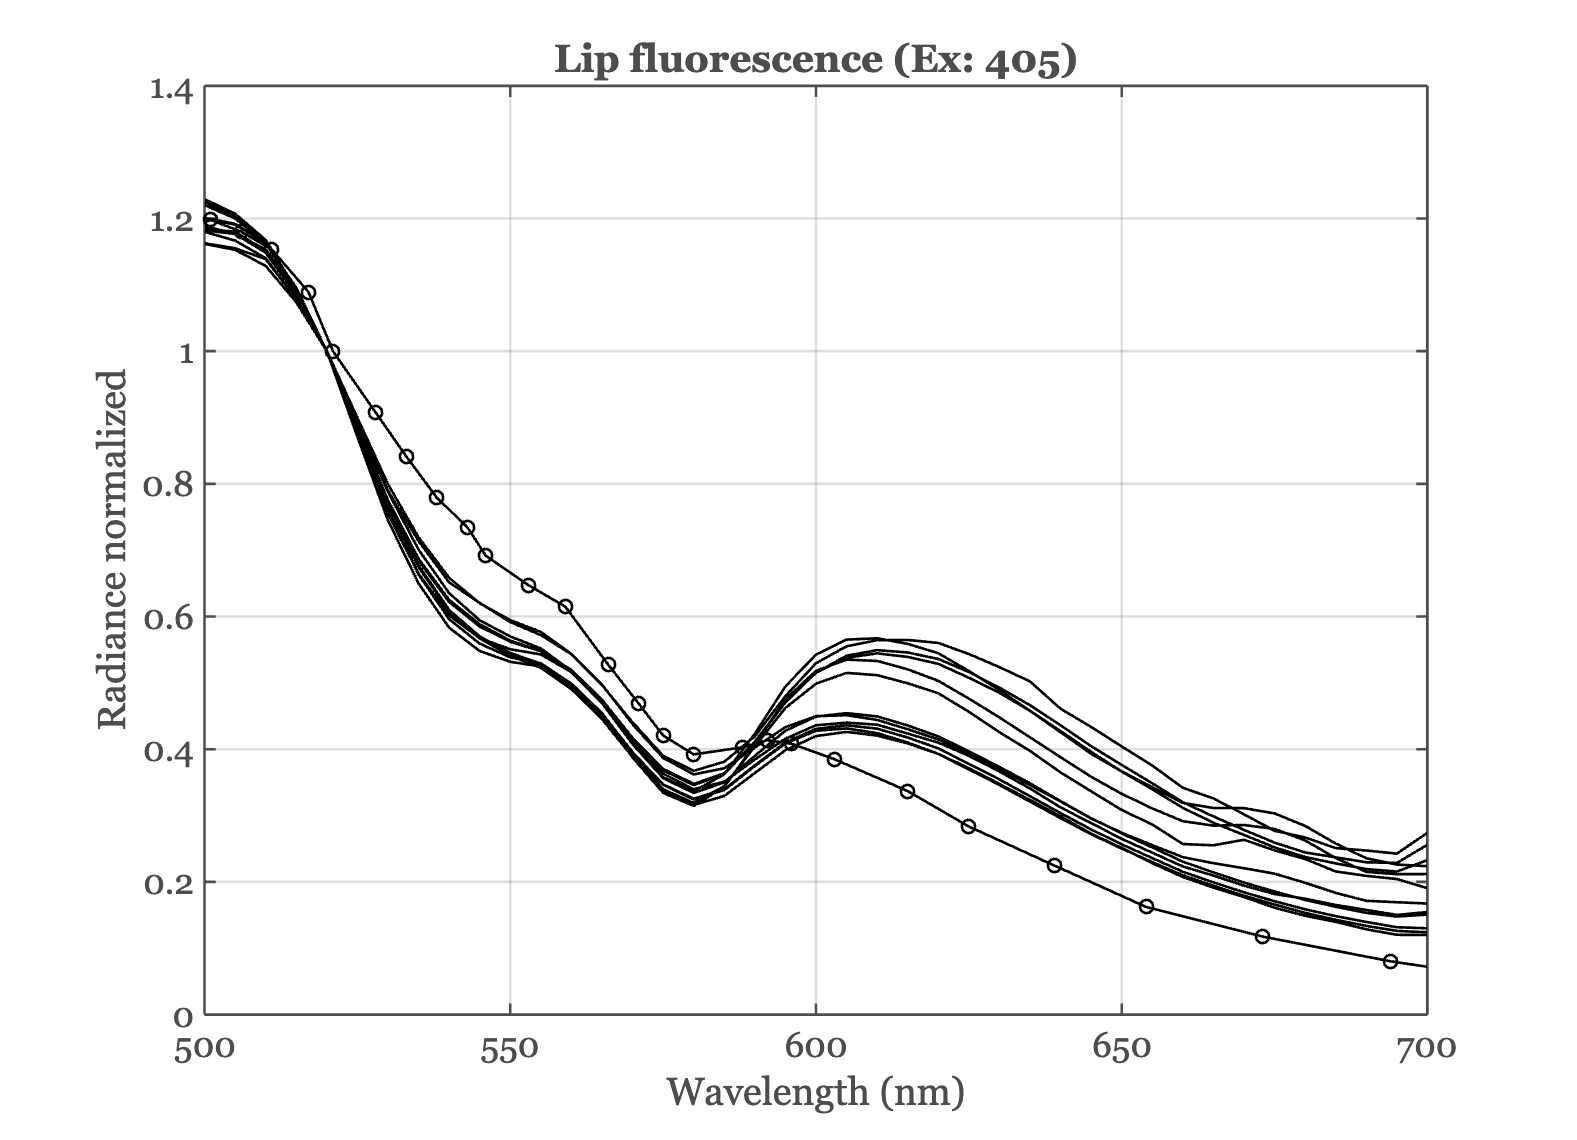

[veldCheekS,wave] = ieReadSpectra('CheekVeld2003.mat'); 
wave = round(wave);
veldCheek = ieReadSpectra('CheekVeld2003.mat',waves); 

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',nWave);

ieFigure;
plot(waves,data405,'k-'); hold on;
% 521 is the closest we have for normalization
plot(wave,veldCheekS/veldCheekS(wave == nWave+1),'ko-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized');
grid on; set(gca,'xlim',[500 700]);
title('Lip fluorescence (Ex: 405)');

## Tongue, all subjects at 405 nm

Read in the files at all excitation levels

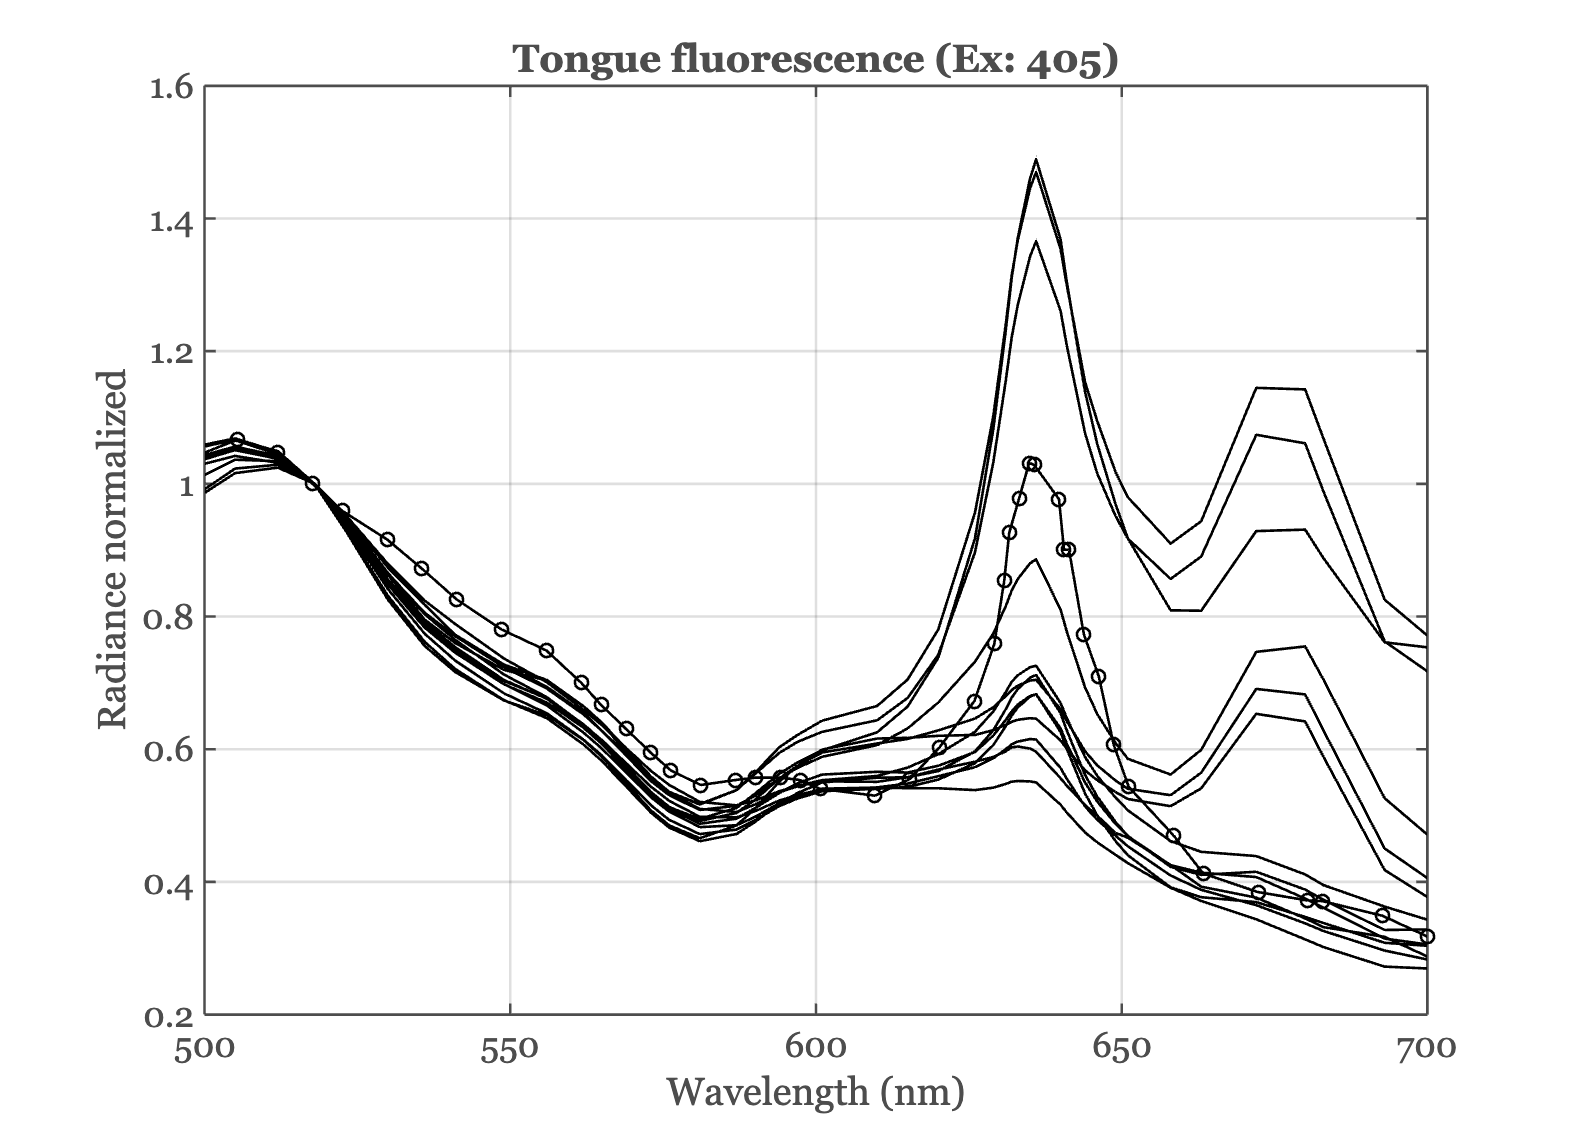

[veldTongueS, wave] = ieReadSpectra('TongueVeld2003.mat');
waves = round(wave);
veldTongue = ieReadSpectra('TongueVeld2003.mat',waves); 

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);

% 518 is this closest we have for normalization
data405 = oeReadFiles(files405,'waves',waves,'normalized wave',nWave-2);

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(wave,veldTongue/veldTongue(waves == nWave-2),'ko-');
xlabel('Wavelength (nm)'); ylabel('Radiance normalized');
set(gca,'xlim',[500 700]); grid on;
title('Tongue fluorescence (Ex: 405)');

## Comparison with de Veld data (Figure 10A)

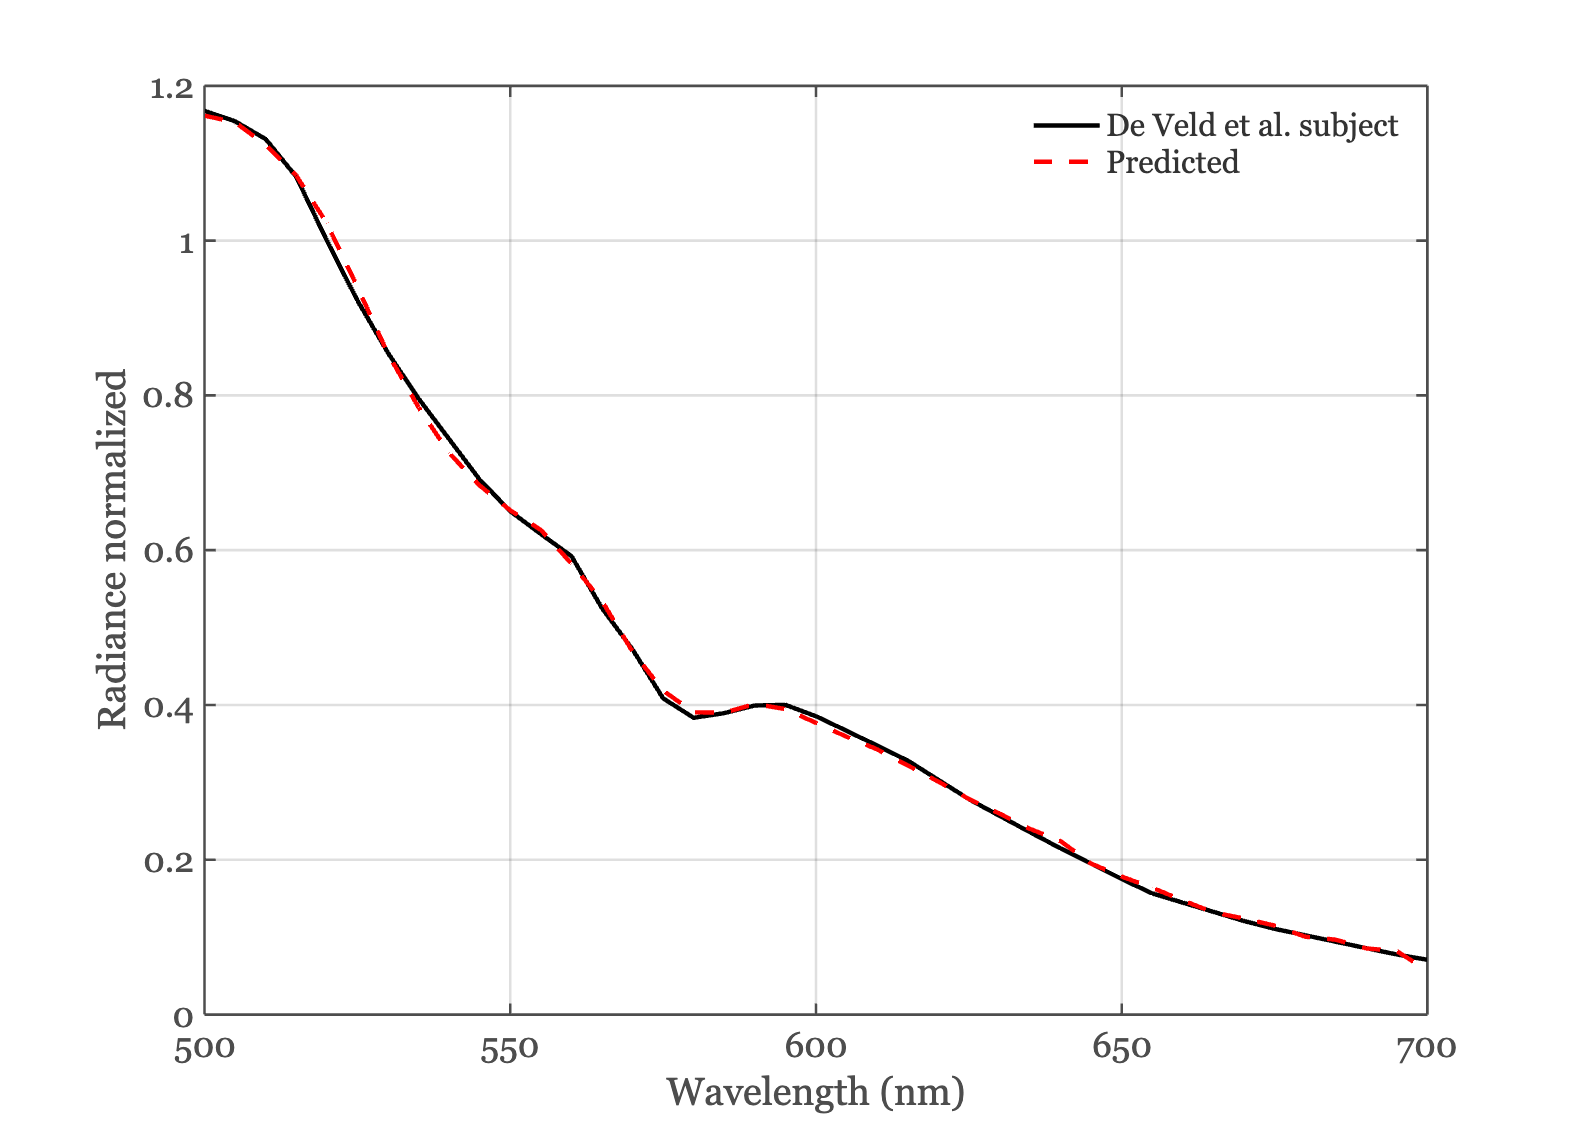

waves = 500:5:700;
veldCheek = ieReadSpectra('CheekVeld2003.mat',waves); 
veldCheek = veldCheek/veldCheek(waves==520);

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);
files415 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);
lipFiles = cat(1,files405,files415);

data405 = oeReadFiles(lipFiles,'waves',waves,'normalized wave',nWave);
wgts = pinv(data405)*veldCheek;
veldCheekP = data405*wgts;

ieFigure;
plot(waves,veldCheek,'k-',waves,veldCheekP,'r--', 'LineWidth',2);
grid on;
legend({'De Veld et al. subject','Predicted'});
xlabel('Wavelength (nm)');
ylabel('Radiance normalized');
exportgraphics(gcf,fullfile(oeTongueLipRootPath,'figures','figure10A.png'),'Resolution',150);

## Tongue comparison with deVeld (Figure 10B)

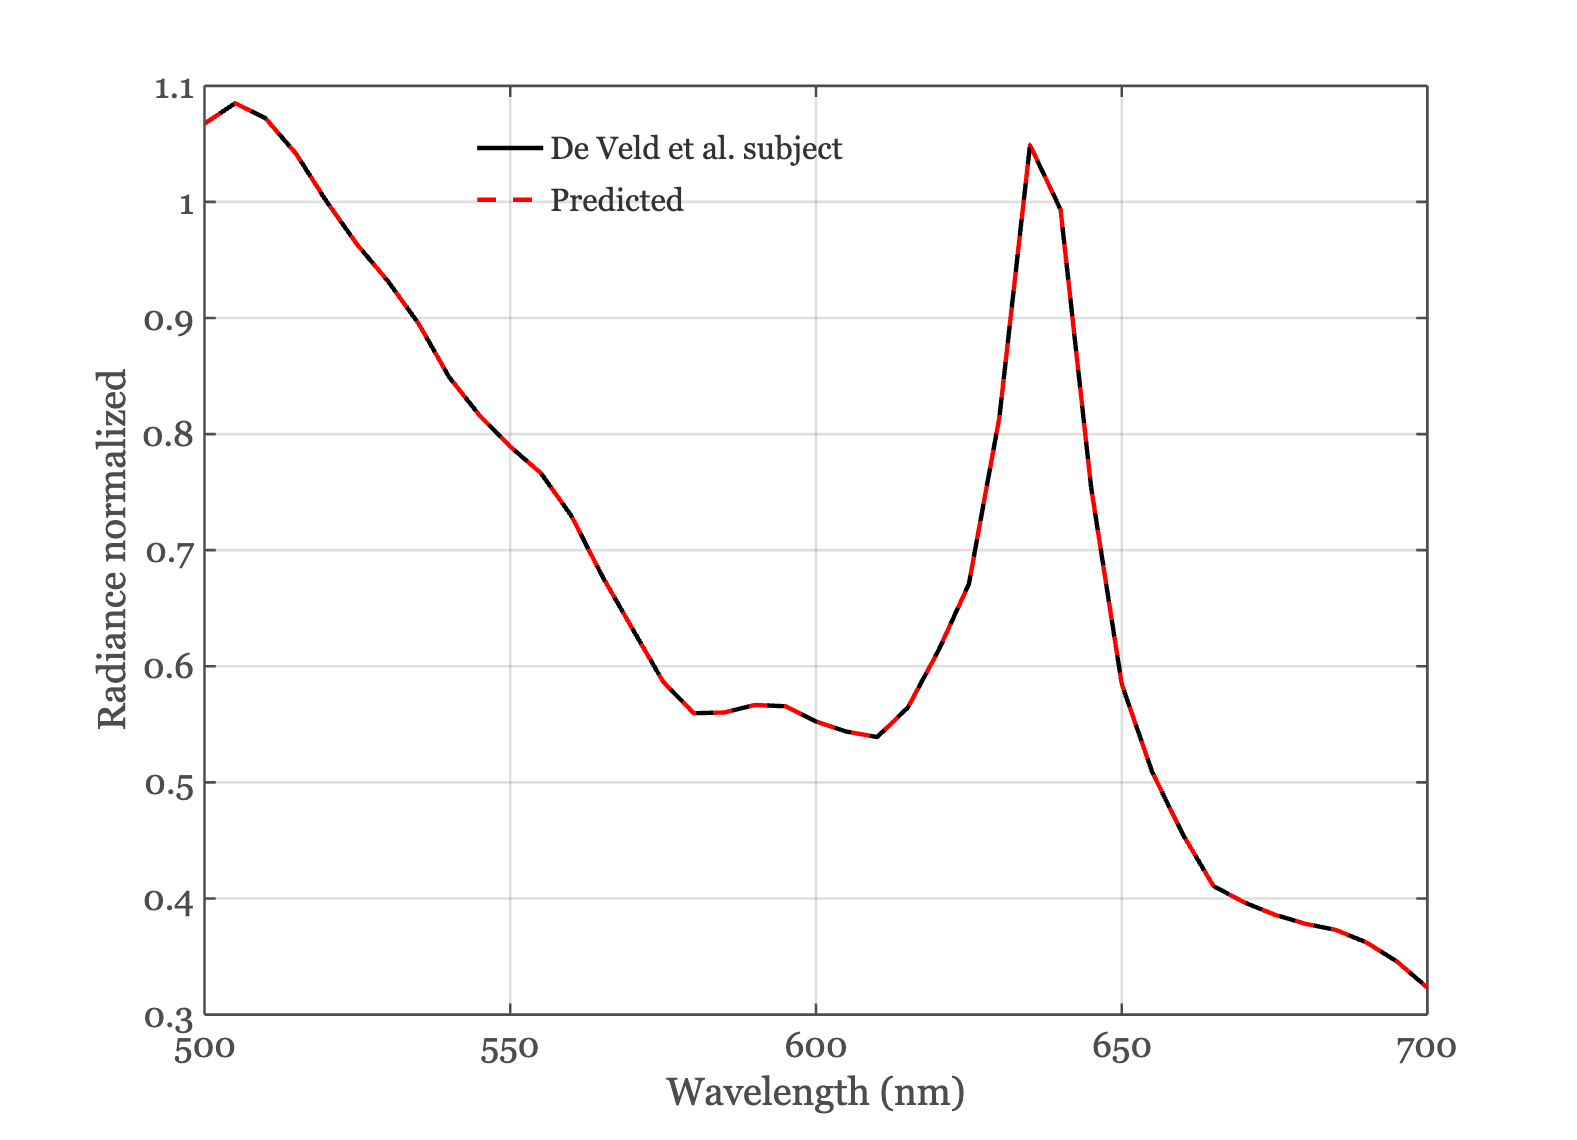

veldTongue = ieReadSpectra('TongueVeld2003.mat',waves); 

% Normalize to 520 nm
veldTongue = veldTongue/veldTongue(waves== 520);

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);
eWave = 415;
files415 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);
tongueFiles = cat(1,files405,files415);

data405 = oeReadFiles(tongueFiles,'waves',waves,'normalized wave',nWave);
wgts = pinv(data405)*veldTongue;
veldTongueP = data405*wgts;

ieFigure;
plot(waves,veldTongue,'k-',waves,veldTongueP,'r--', 'LineWidth',2);
grid on;
legend({'De Veld et al. subject','Predicted'});
xlabel('Wavelength (nm)'); ylabel('Radiance normalized');
legend(["De Veld et al. subject", "Predicted"], "Position", [0.3191 0.7974 0.2, 0.10])

exportgraphics(gcf,fullfile(oeTongueLipRootPath,'figures','figure10B.png'),'Resolution',150);